# 利用以往灯光与GDP数据生成模型

## 导入数据

light_data_table = readtable('light_data.xlsx');
GDP_data_table = readtable('GDP_data.xlsx');
area_data_table = readtable('area_data.xlsx');
light_2017=light_data_table.Var2;
light_2018=light_data_table.Var3;
light_2019=light_data_table.Var4;
light_2020=light_data_table.Var5;
area_data=[area_data_table.Var2];
GDP_2017=GDP_data_table.Var2./area_data*100;
GDP_2018=GDP_data_table.Var3./area_data*100;
GDP_2019=GDP_data_table.Var4./area_data*100;
GDP_2020=GDP_data_table.Var5./area_data*100;
province=GDP_data_table.Var1;

all_light_data = [light_2017; light_2018; light_2019];
all_GDP_data = [GDP_2017; GDP_2018; GDP_2019];
Data=[all_light_data,all_GDP_data];

## 异常值处理

coefficients_linear = polyfit(all_light_data, all_GDP_data, 1);
model_linear= @(x) coefficients_linear(1) * x + coefficients_linear(2);
equation = sprintf('GDP = %.4fx + %.4f', coefficients_linear(1), coefficients_linear(2));
disp('线性拟合模型公式：');

线性拟合模型公式：


disp(equation);

GDP = 5.9745x + -24.9084


z_scores_light = zscore(all_light_data);
z_scores_GDP = zscore(all_GDP_data);
z_threshold = 2.58

z_threshold = 2.5800

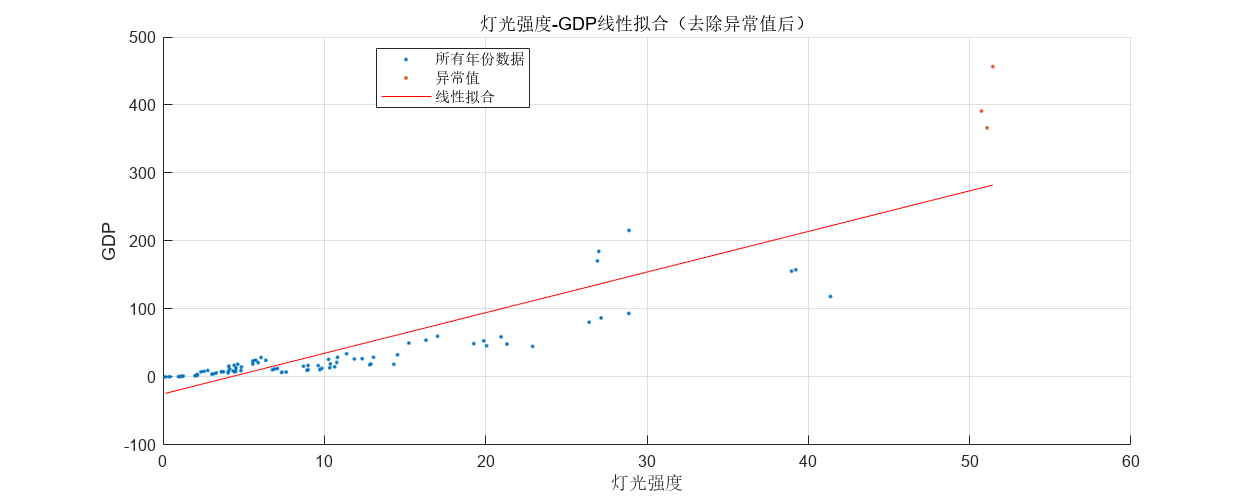

outlier_indices = find(abs(z_scores_light) > z_threshold | abs(z_scores_GDP) > z_threshold);
cleaned_light_data = all_light_data;
cleaned_GDP_data = all_GDP_data;

% Sign the cleaned data.
cleaned_light_data(outlier_indices) = NaN;
cleaned_GDP_data(outlier_indices) = NaN;

figure('Position', [100, 100, 1000, 400]); 
scatter(all_light_data, all_GDP_data, '.', 'DisplayName', '所有年份数据');
hold on;
scatter(all_light_data(outlier_indices), all_GDP_data(outlier_indices), '.', 'DisplayName', '异常值');
fplot(model_linear, [min(all_light_data), max(all_light_data)], 'r-', 'DisplayName', '线性拟合');
xlabel('灯光强度');
ylabel('GDP');
legend('Location', 'best');
grid on;
title('灯光强度-GDP线性拟合（去除异常值后）');

cleaned_light_data = rmmissing(cleaned_light_data);
cleaned_GDP_data = rmmissing(cleaned_GDP_data);

## 拟合生成模型

### e指数拟合

coefficients_exp = fit(cleaned_light_data, cleaned_GDP_data, 'exp1');
model_exp1 = @(x) coefficients_exp.a * exp(coefficients_exp.b * x);
equation_exp = sprintf('GDP = %.4fe^{%.4fx}', coefficients_exp.a, coefficients_exp.b);
disp('指数拟合模型公式：');

指数拟合模型公式：


disp(equation_exp);

GDP = 13.6130e^{0.0641x}


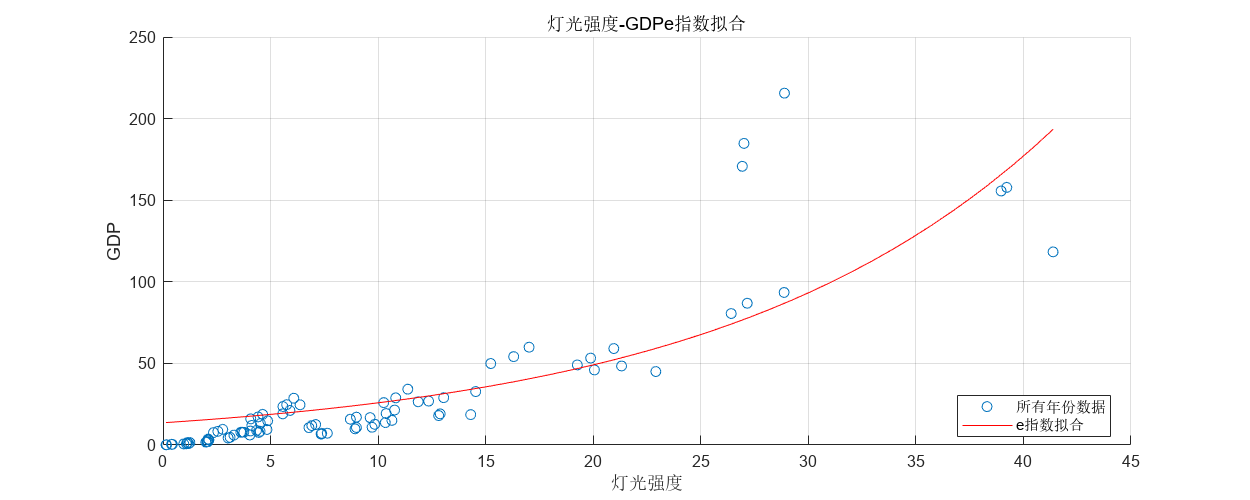

figure('Position', [100, 100, 1000, 400]); 
scatter(cleaned_light_data, cleaned_GDP_data, 'o', 'DisplayName', '所有年份数据');
hold on;
fplot(model_exp1, [min(cleaned_light_data), max(cleaned_light_data)], 'r-', 'DisplayName', 'e指数拟合');
xlabel('灯光强度');
ylabel('GDP');
legend('Location', 'best');
grid on;
title('灯光强度-GDPe指数拟合');

### 多项式拟合

degree_poly=3 % 调节多项式次数

degree_poly = 3

coefficients_poly = polyfit(cleaned_light_data, cleaned_GDP_data, degree_poly);
if degree_poly == 1
    model_poly = @(x) coefficients_poly(1) * x + coefficients_poly(2);
    equation_poly = sprintf('GDP = %.4fx + %.4f', coefficients_poly(1), coefficients_poly(2));
elseif degree_poly == 2
    model_poly = @(x) coefficients_poly(1) * x.^2 + coefficients_poly(2) * x + coefficients_poly(3);
    equation_poly = sprintf('GDP = %.4fx^2 + %.4fx + %.4f', coefficients_poly(1), coefficients_poly(2), coefficients_poly(3));
elseif degree_poly == 3
    model_poly = @(x) coefficients_poly(1) * x.^3 + coefficients_poly(2) * x.^2 + coefficients_poly(3) * x + coefficients_poly(4);
    equation_poly = sprintf('GDP = %.4fx^3 + %.4fx^2 + %.4fx + %.4f', coefficients_poly(1), coefficients_poly(2), coefficients_poly(3), coefficients_poly(4));
elseif degree_poly == 4
    model_poly = @(x) coefficients_poly(1) * x.^4 + coefficients_poly(2) * x.^3 + coefficients_poly(3) * x.^2 + coefficients_poly(4) * x + coefficients_poly(5);
    equation_poly = sprintf('GDP = %.4fx^4 + %.4fx^3 + %.4fx^2 + %.4fx + %.4f', coefficients_poly(1), coefficients_poly(2), coefficients_poly(3), coefficients_poly(4), coefficients_poly(5));
elseif degree_poly == 5
    model_poly = @(x) coefficients_poly(1) * x.^5 + coefficients_poly(2) * x.^4 + coefficients_poly(3) * x.^3 + coefficients_poly(4) * x.^2 + coefficients_poly(5) * x + coefficients_poly(6);
    equation_poly = sprintf('GDP = %.4fx^5 + %.4fx^4 + %.4fx^3 + %.4fx^2 + %.4fx + %.4f', coefficients_poly(1), coefficients_poly(2), coefficients_poly(3), coefficients_poly(4), coefficients_poly(5), coefficients_poly(6));
else
    error('Unsupported degree');
end

disp('多项式拟合模型公式：');

多项式拟合模型公式：


disp(equation_poly);

GDP = -0.0069x^3 + 0.4309x^2 + -2.7746x + 9.7856


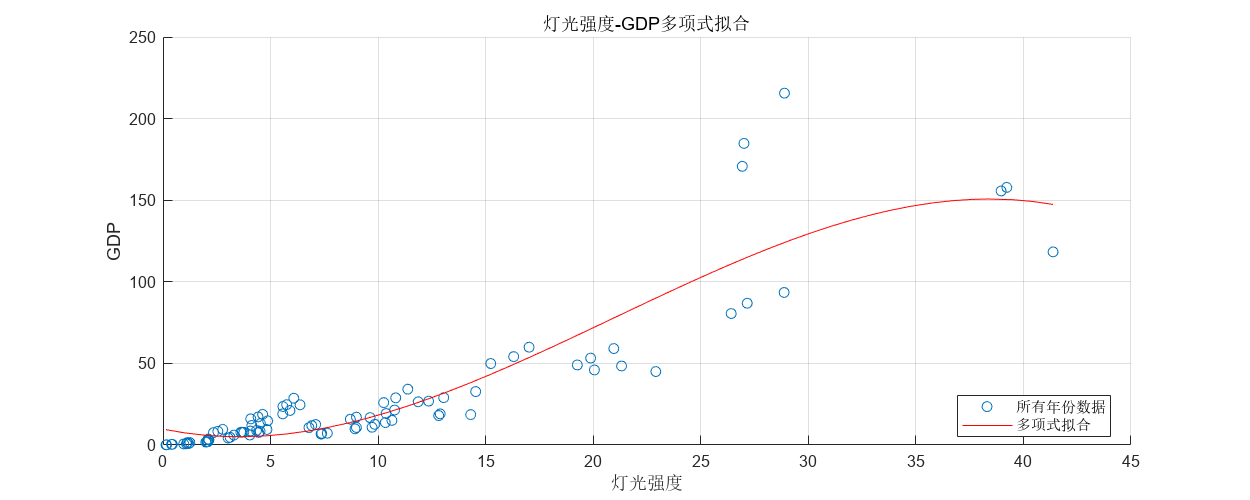


figure('Position', [100, 100, 1000, 400]);
scatter(cleaned_light_data, cleaned_GDP_data, 'o', 'DisplayName', '所有年份数据');
hold on;
fplot(model_poly, [min(cleaned_light_data), max(cleaned_light_data)], 'r-', 'DisplayName', '多项式拟合');
xlabel('灯光强度');
ylabel('GDP');
legend('Location', 'best');
grid on;
title('灯光强度-GDP多项式拟合');

### fourier`拟合`

degree_Fourier = 1; % 设置Fourier级数的次数
f = fit(cleaned_light_data, cleaned_GDP_data, ['fourier', num2str(degree_Fourier)]);
model_fourier = formula(f);
disp('Fourier级数拟合模型公式：');

Fourier级数拟合模型公式：


disp(model_fourier);

 a0 + a1*cos(x*w) + b1*sin(x*w)


model_fourier = @(x) feval(f, x);

figure('Position', [100, 100, 1000, 400]);
scatter(cleaned_light_data, cleaned_GDP_data, 'o', 'DisplayName', '所有年份数据');
hold on;
fplot(model_fourier, [min(cleaned_light_data), max(cleaned_light_data)], 'r-', 'DisplayName', 'Fourier级数拟合');

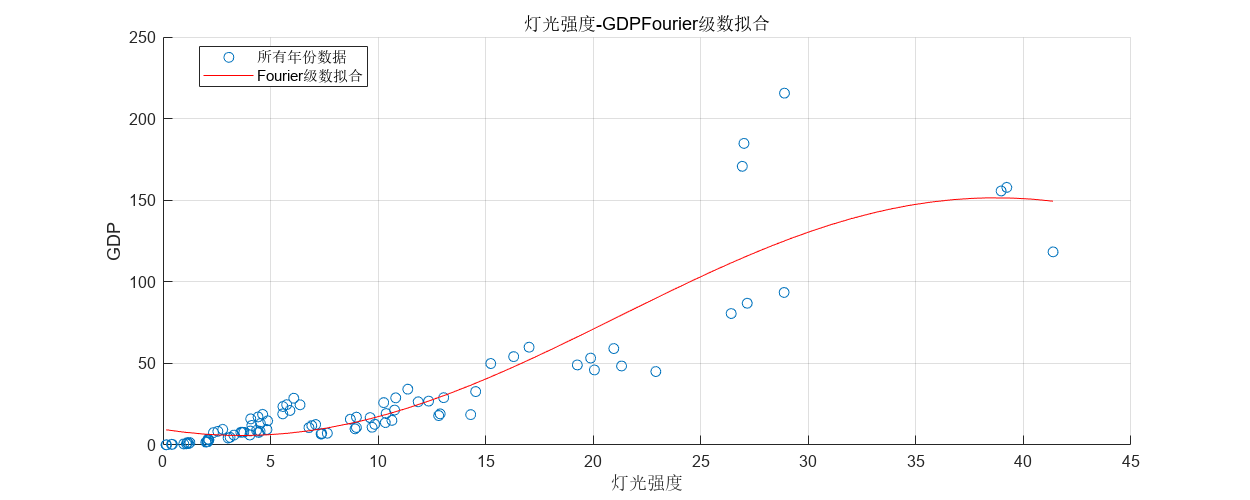

xlabel('灯光强度');
ylabel('GDP');
legend('Location', 'best');
grid on;
title('灯光强度-GDPFourier级数拟合');

## 拟合度分析

% 计算e指数拟合度
Predicted_exp1 = model_exp(cleaned_light_data);
Show_fitDegree(Predicted_exp1,cleaned_GDP_data,2);

SSE: 51962.9439
R-square: 0.67924
Adjusted R-square: 0.67187
RMSE: 24.0284


% 计算多项式拟合度
Predicted_poly =model_poly(cleaned_light_data);
Show_fitDegree(Predicted_poly,cleaned_GDP_data,degree_poly);

SSE: 29367.4277
R-square: 0.81872
Adjusted R-square: 0.8124
RMSE: 18.0639


% 计算Fourier拟合度
Predicted_Fourier = model_fourier( cleaned_light_data);
Show_fitDegree(Predicted_Fourier,cleaned_GDP_data,degree_Fourier);

SSE: 28884.6628
R-square: 0.8217
Adjusted R-square: 0.81967
RMSE: 17.9148


- 小注：在多项式（一次）时，完全符合示例结果，拟合度：Fourier（一级）>多项式（一次）>e指数。但在多项式次数在4次以上后，拟合度大于Fourier（一级）,但要注意过度拟合问题。

## 运用模型进行预测

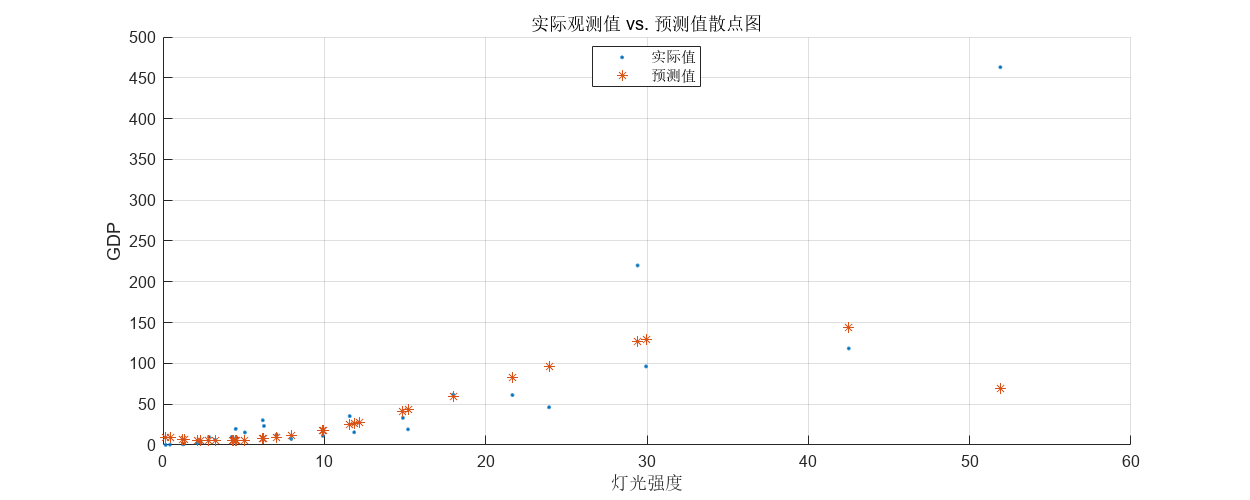

MODEL=model_poly;

X=light_2020;
Predict=MODEL(X);
Real=GDP_2020;

figure('Position', [100, 100, 1000, 400]);
scatter(light_2020, Real, '.', 'DisplayName', '实际值');
hold on;
scatter(light_2020, Predict, '*', 'DisplayName', '预测值');
xlabel('灯光强度');
ylabel('GDP');
legend('Location', 'best');
title('实际观测值 vs. 预测值散点图');
grid on;
hold off;

### 误差分析

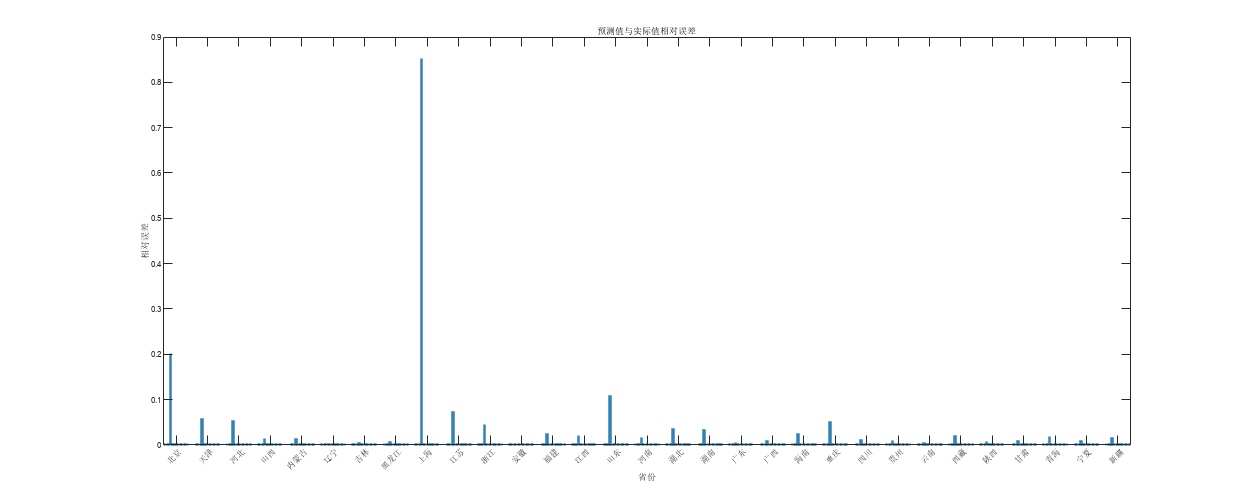

error=abs(Predict-Real)/Real;

bar(1:length(province), error, 0.8, 'FaceColor', [0.5 0.7 0.9], 'EdgeColor', [0.2 0.5 0.7], 'LineWidth', 1.5);
xticks(1:length(province));
xticklabels(province);
xtickangle(45); 
set(gca, 'FontSize', 5);
xlabel('省份');
ylabel('相对误差');
title('预测值与实际值相对误差');